# 2. Initial processes on raw NMR data

In this example, we import a sample NMR data and perform a few standard NMR data processing operations: DC offset correction, apodisation, zerofilling, and Fourier transform. 

### 2.1 Experimental data import

The molecule we are dealing with is 4-fluorophenol, a common pharmaceutical precursor. Data kindly provided by Prof. Ilya Kuprov, University of Southampton. This dataset has already been exported by the NMR instrument into [.mat file](https://www.mathworks.com/help/matlab/ref/matlab.io.matfile.html) that may be loaded and plotted directly:

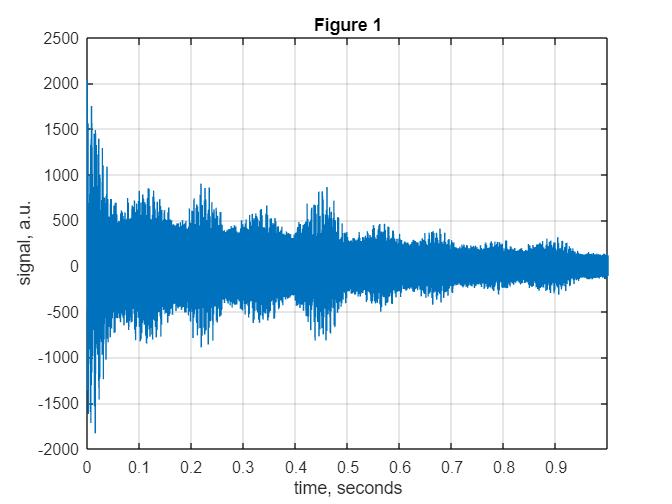

load('4-fluorophenol_nmr.mat','time_axis','fid');
plot(time_axis,real(fid)); xlim tight; grid;
xlabel('time, seconds'); ylabel('signal, a.u.'); title('Figure 1');

where we took the real part before plotting. The Free Induction Decay ([FID](https://chem.libretexts.org/Bookshelves/Physical_and_Theoretical_Chemistry_Textbook_Maps/Quantitative_NMR_(Larive_and_Korir)/01%3A_Basic_NMR_Theory/1.09%3A_What_is_the_Free_Induction_Decay)) is complex because, by a convenient historical convention, the instrument stores X magnetization in the real part, and Y magnetization in the imaginary part of the complex signal. 

Figure 1 shows an oscillation; this is our nuclear magnetic moments (in this case, of 1H nuclei) rotating around the direction of the external magnetic field. Their frequencies carry structural information that is useful to chemists.

### **2.2 DC offset correction**

NMR instruments are not perfect. One common experimental artefact is a small amount of direct current mixed into what is supposed to be an oscillating current with a strictly zero mean value:

disp('Mean value (DC offset): '); disp(mean(fid));

Mean value (DC offset): 
  -0.3104 + 0.3027i



Thankfully, that is very easy to correct: 

fid=fid-mean(fid);

Note the feature that MATLAB calls *implicit singleton expansion*: when a number is subtracted from a vector, it is subtracted from every element of this vector. This has just saved us a tedious *for* loop.

### **2.3 Apodisation**

Another common instrumental problem is signal truncation. Note that the XY plane magnetization has not had enough time to decay to zero in Figure 1, and the signal is therefore incomplete. This will cause us trouble if we try to look at the frequency spectrum using the Fourier transform:

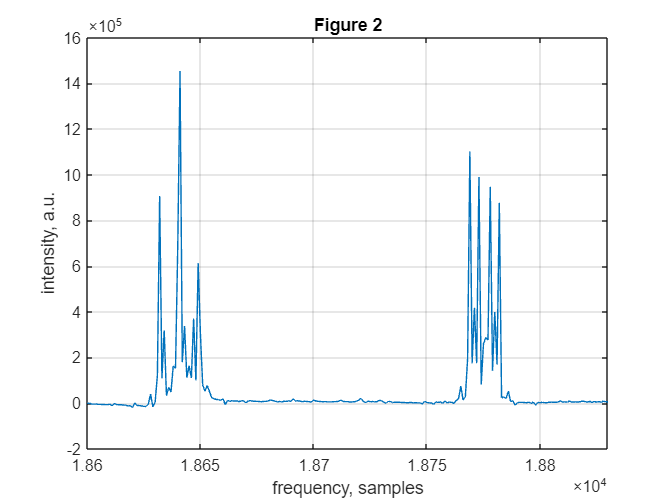

plot(real(fft(fid))); xlim([18600 18830]); grid; title('Figure 2');
xlabel('frequency, samples'); ylabel('intensity, a.u.'); 

The wobbles at the base of these peaks are signal truncation artefacts. To eliminate them, we need to force the FID in Figure 1 decay to zero, like it happens in complete data sets. One way of doing it is to multiply the FID by a decaying function; this is called *apodisation*, and the function is called *window function.* An exponential window function is a good choice:

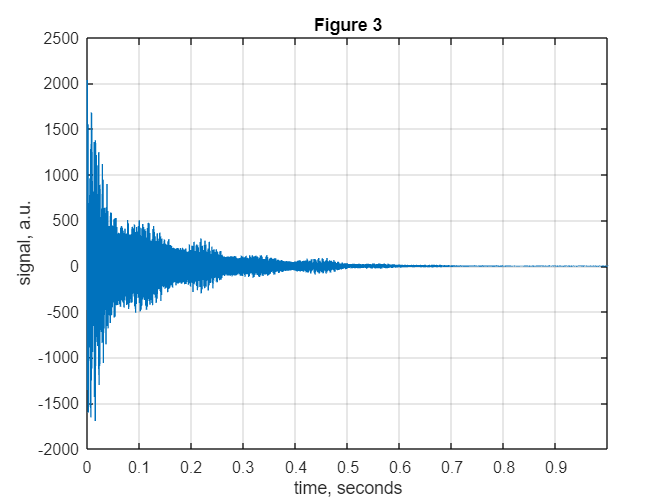

win_fun=exp(-5*time_axis); fid=win_fun.*fid;
plot(time_axis,real(fid)); xlim tight; grid;
xlabel('time, seconds'); ylabel('signal, a.u.'); title('Figure 3');

The FID now neatly decays to zero, and the Fourier transform is therefore free of artefacts:

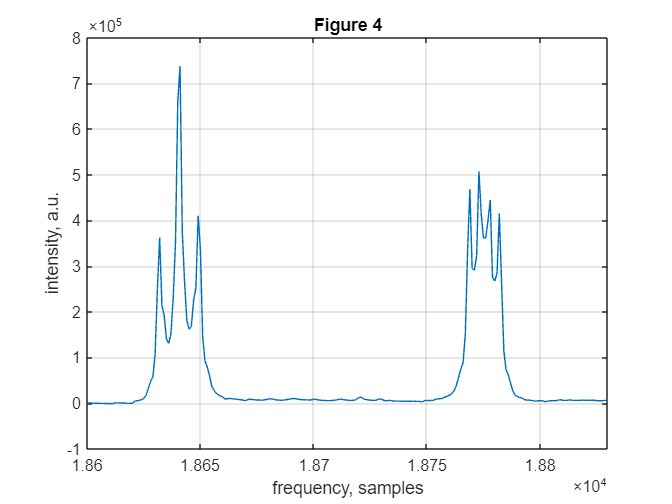

plot(real(fft(fid))); xlim([18600 18830]); title('Figure 4');
xlabel('frequency, samples'); ylabel('intensity, a.u.'); grid;

### 2.4 Zerofilling

A cosmetic matter is that the signals in Figure 4 are not well digitized - only a few points per peak. This can make further processing (for example, integration) inaccurate. An elegant way around this makes use of the fact that padding the time domain signal with zeros in Figure 3 corresponds to interpolating the frequency domain signal in Figure 4. Padding with zeros is easy:

fid=[fid; zeros(size(fid))];

and we also need to recalculate the time axis:

time_axis=linspace(0,2*time_axis(end),numel(fid))';

With all of that in place:

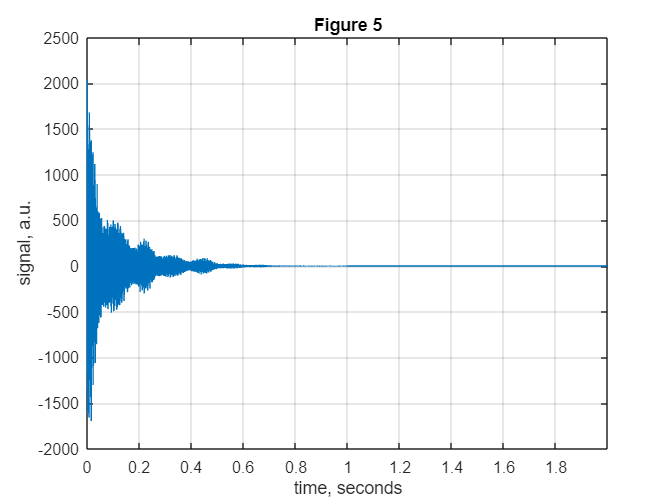

plot(time_axis,real(fid)); xlim tight; grid;
xlabel('time, seconds'); ylabel('signal, a.u.'); title('Figure 5');

where we now have a long trail of zeroes at the end of the signal. The Fourier transform now looks much better:

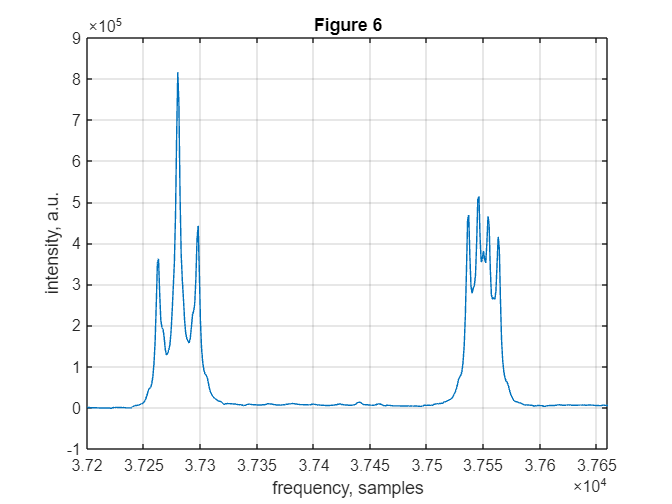

plot(real(fft(fid))); xlim(2*[18600 18830]); title('Figure 6');
xlabel('frequency, samples'); ylabel('intensity, a.u.'); grid;

and even a small peak (that previously was not digitized properly) is visible in the signal on the right.